% import firm table 
% excersice 3.1
xt=readtable("Firm.xlsx",ReadRowNames=true);

summary(xt);


xt: 107×9 table

Variables:

    Surname: cell array of character vectors
    Name: cell array of character vectors
    Gender: cell array of character vectors
    BirthDate: datetime
    Education: cell array of character vectors
    Wage: double
    CommutingTime: double
    SmartWorkHours: double
    Seniority: double

Statistics for applicable variables:

                      NumMissing          Min              Median               Max                    Mean                    Std       

    Surname               0                                                                                                              
    Name                  0                           

% display the summary of the first 6 columns
summary(xt(:,1:6))


107×6 table

Variables:

    Surname: cell array of character vectors
    Name: cell array of character vectors
    Gender: cell array of character vectors
    BirthDate: datetime
    Education: cell array of character vectors
    Wage: double

Statistics for applicable variables:

                 NumMissing          Min              Median               Max                    Mean                    Std       

    Surname          0                                                                                                              
    Name             0                                                                                                              
    Gender           0                                       

% creating and managing catagorical array
% Excerscice 3.2
c=["School Leaving Certificate","Highschool Graduate","Bacholr Degree","Master's Degree"];
cat = categorical(c, Ordinal=true);


% here because we didn't specify the order the min and max will not work so
% it must be like 

cat=categorical(c,["School Leaving Certificate","Highschool Graduate","Bacholr Degree","Master's Degree"],Ordinal=true);

## now try min and max of cat

disp(min(cat));

     School Leaving Certificate 



disp(max(cat));

     Master's Degree 



disp(median(cat));

     Bacholr Degree 



## add new value

cat = addcats(cat,'Preparatory','After','Highschool Graduate');

xt.Gender=categorical(xt.Gender);
xt.Education =categorical(xt.Education,["A","B","C"],Ordinal=true);

% now display the summary of xt
summary(xt);


xt: 107×9 table

Variables:

    Surname: cell array of character vectors
    Name: cell array of character vectors
    Gender: categorical (2 categories)
    BirthDate: datetime
    Education: ordinal categorical (3 categories)
    Wage

## univariate analysis of categorical variable

% visualize frequency distribution 
tabulate(xt.Education);

  Value    Count   Percent
      A       24     22.43%
      B       37     34.58%
      C       46     42.99%


tabulate(xt.Gender);

  Value    Count   Percent
      F       46     42.99%
      M       61     57.01%


tabulate(xt.Seniority);

  Value    Count   Percent
      1        3      2.80%
      2        9      8.41%
      3        3      2.80%
      4        3      2.80%
      5        4      3.74%
      6        2      1.87%
      7        5      4.67%
      8        4      3.74%
      9        3      2.80%
     10        4      3.74%
     11        5      4.67%
     12        4      3.74%
     13        4      3.74%
     14        5      4.67%
     15        4      3.74%
     16        7      6.54%
     17        3      2.80%
     18        2      1.87%
     19        4      3.74%
     20        2      1.87%
     21        0      0.00%
     22        1      0.93%
     23        1      0.93%
     24        2      1.87%
     25        1      0.93%
     26        2      1.87%
     27        0      0.00%
     28        3      2.80%
     29        1      0.93%
     30        2      1.87%
     31        5      4.67%
     32        2      1.87%
     33        1      0.93%
     34        1      0.93%
     35        1     

% for nominal data we can only compute the mode
mode(xt.Gender);
% and we can also compute median for ordinal
median(xt.Education)

ans = categorical
     B 


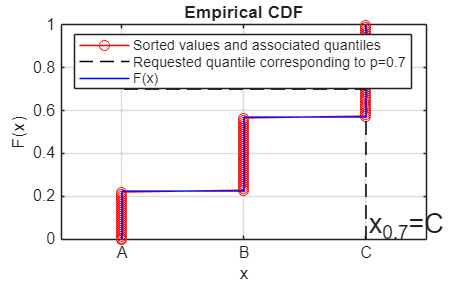

% compute and display 0.7 quantile for education
qed= GUIquantile(xt.Education,0.7);

% Univariante analysis of quantitative variable
% create a table named xtd which is conatining the quantitative value of xt

xtd =[xt.Wage,xt.CommutingTime,xt.SmartWorkHours,xt.Seniority];

% calculate the mean and standatd devation of each xtd
meanv= mean(xtd);
median(xtd);
stdv = std(xtd);

% or we can write the column name of what we want and copy the value
coln =["Wage","CommutingTime","SmartWorkHours","Seniority"];

Xtd = xt{:,coln};

% calculate the standard devation and cofficent of variation
cv = stdv ./ meanv; % Calculate the coefficient of variation
disp(cv); % Display the coefficient of variation

    0.2571    0.3966    0.4310    0.6895



% calculate the skwness
skewnessValues = skewness(Xtd);
disp(skewnessValues);

    1.0981    0.9751    0.8144    0.6588



% calculate the kurtosis
kurtosisValues = kurtosis(Xtd);
disp(kurtosisValues);

    3.7885    3.7216    2.9839    2.5635



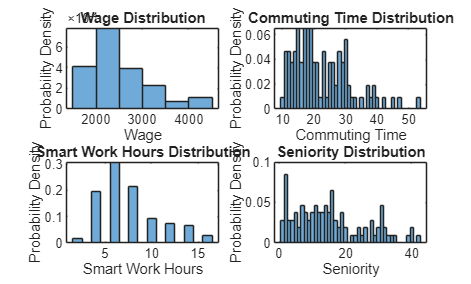

% show the skiwness using graph for all 4 variable
figure;
subplot(2,2,1);
histogram(Xtd(:,1), 'Normalization', 'pdf');
title('Wage Distribution');
xlabel('Wage');
ylabel('Probability Density');
subplot(2,2,2);
histogram(Xtd(:,2), 'Normalization', 'pdf');
title('Commuting Time Distribution');
xlabel('Commuting Time');
ylabel('Probability Density');
subplot(2,2,3);
histogram(Xtd(:,3), 'Normalization', 'pdf');
title('Smart Work Hours Distribution');
xlabel('Smart Work Hours');
ylabel('Probability Density');
subplot(2,2,4);
histogram(Xtd(:,4), 'Normalization', 'pdf');
title('Seniority Distribution');
xlabel('Seniority');
ylabel('Probability Density');

## Freque. Distribution of quantitative variable

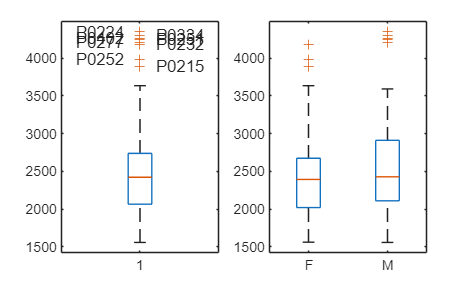

subplot(1,2,1)
boxplot(xt.Wage)
add2boxplot(xt(:,"Wage"))

subplot(1,2,2)
boxplot(xt.Wage,xt.Gender)

% compute 0.1 quantile of wage
ran =[0.1:0.05:0.9];

p1=xt.Gender=="F";
p2=xt.Gender=="M";

p11=xt{p1,"Wage"};
p22=xt{p2,"Wage"};

qf=quantile(p11,ran);
qm=quantile(p22,ran);

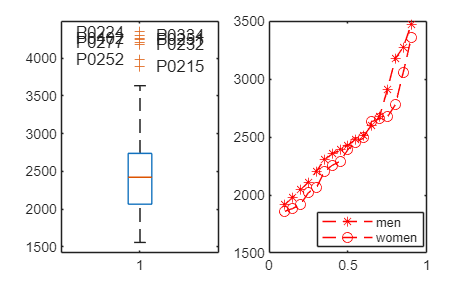

plot(ran,qm,'r--*',ran,qf,'r--o')
legend(["men" "women"],Location="best")

X=readtable("Firm.xlsx",ReadRowNames=true);

% Create pivoted table
pivotedData = pivot(X, Rows="Gender", Columns="Education", ...
    RowLabelPlacement="rownames")

pivotedData = 2×3 table
         A     B     C 
         __    __    __

    F    10    15    21
    M    14    22    25


pivot(X,Rows="Gender",Columns="Education",DataVariable="Wage",Method="mean",IncludeTotals=true)

ans = 3×5 table
         Gender           A         B         C       Overall_mean
    ________________    ______    ______    ______    ____________

    {'F'           }    2169.5      2356    2710.2       2477.2   
    {'M'           }    2061.4    2659.6    2846.9       2599.1   
    {'Overall_mean'}    2106.5    2536.5    2784.5       2546.7   


pivot(X,Rows="Gender",Columns="Education",DataVariable="Wage",Method="mean",IncludeTotals=true,RowLabelPlacement="rownames")

ans = 3×4 table
                      A         B         C       Overall_mean
                    ______    ______    ______    ____________

    F               2169.5      2356    2710.2       2477.2   
    M               2061.4    2659.6    2846.9       2599.1   
    Overall_mean    2106.5    2536.5    2784.5       2546.7   


pivot(X,Rows="Wage",Columns="Education",RowsBinMethod=[1500:600:4500])

ans = 5×4 table
     disc_Wage      A     B     C 
    ____________    __    __    __

    [1500, 2100)    12    10     7
    [2100, 2700)    11    18    20
    [2700, 3300)     1     4    10
    [3300, 3900)     0     4     3
    [3900, 4500]     0     1     6


x1=X;

x1.Wage(1)=2000;

pivot(x1,Rows="Wage",Columns="Education",RowsBinMethod=[1500:500:4500])

ans = 6×4 table
     disc_Wage      A     B     C 
    ____________    __    __    __

    [1500, 2000)    10     5     6
    [2000, 2500)    12    15    16
    [2500, 3000)     2     9    10
    [3000, 3500)     0     5     7
    [3500, 4000)     0     2     2
    [4000, 4500]     0     1     5


pivot(x1,Rows="Wage",Columns="Education",RowsBinMethod=(1500:500:4500),IncludedEdge="right")

ans = 6×4 table
     disc_Wage      A     B     C 
    ____________    __    __    __

    [1500, 2000]    11     5     6
    (2000, 2500]    11    15    16
    (2500, 3000]     2     9    10
    (3000, 3500]     0     5     7
    (3500, 4000]     0     2     2
    (4000, 4500]     0     1     5


pivot(x1,Rows=["Gender" "Education"],Columns="Seniority",ColumnsBinMethod=(0:15:45))

ans = 6×5 table
    Gender    Education    [0, 15)    [15, 30)    [30, 45]
    ______    _________    _______    ________    ________

    {'F'}       {'A'}         4           4          2    
    {'F'}       {'B'}         8           5          2    
    {'F'}       {'C'}        12           4          5    
    {'M'}       {'A'}         8           5          1    
    {'M'}       {'B'}        16           4          2    
    {'M'}       {'C'}        10          11          4    


pivot(x1,Rows=["Seniority" "Wage"],Columns="Education",RowsBinMethod=[[0:15:45] [1500:1000:4500]])

ans = 9×5 table
    disc_Seniority     disc_Wage      A     B     C 
    ______________    ____________    __    __    __

       [0, 15)        [1500, 2500)    12    19    20
       [0, 15)        [2500, 3500)     0     5     2
       [0, 15)        [3500, 4500]     0     0     0
       [15, 30)       [1500, 2500)     9     1     2
       [15, 30)       [2500, 3500)     0     8    13
       [15, 30)       [3500, 4500]     0     0     0
       [30, 45)       [1500, 2500)     1     0     0
       [30, 45)       [2500, 3500)     2     1     2
       [30, 45)       [3500, 4500]     0     3     7


data =0:5:45;

edge=[0,20,30,45]

edge =      0    20    30    45


bin=discretize(data,edge);

pivot(x1,Rows=["Gender", "Seniority"],RowsBinMethod=["none" ,[0 20 30 45]],Columns="Education",DataVariable="Wage",Method="median")

Error using matlab.internal.math.parsegroupbins (line 78)
Invalid value for 'RowsBinMethod'.

Error in pivot>validateBinMethod (line 519)
    [bins,didexpand,expandvars] = matlab.internal.math.parsegroupbins(bins,numG,"pivot:" + flag);
    ^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^